# Project ESP Measuring Power

This ESP serves as an introduction to measuring the harvested power of your windmill. 

You will need: 

- Your prototype

- Wind Tunnel/Fan or Fan 

- Anemometer (Wind Meter)

- Your Arduino and Laptop

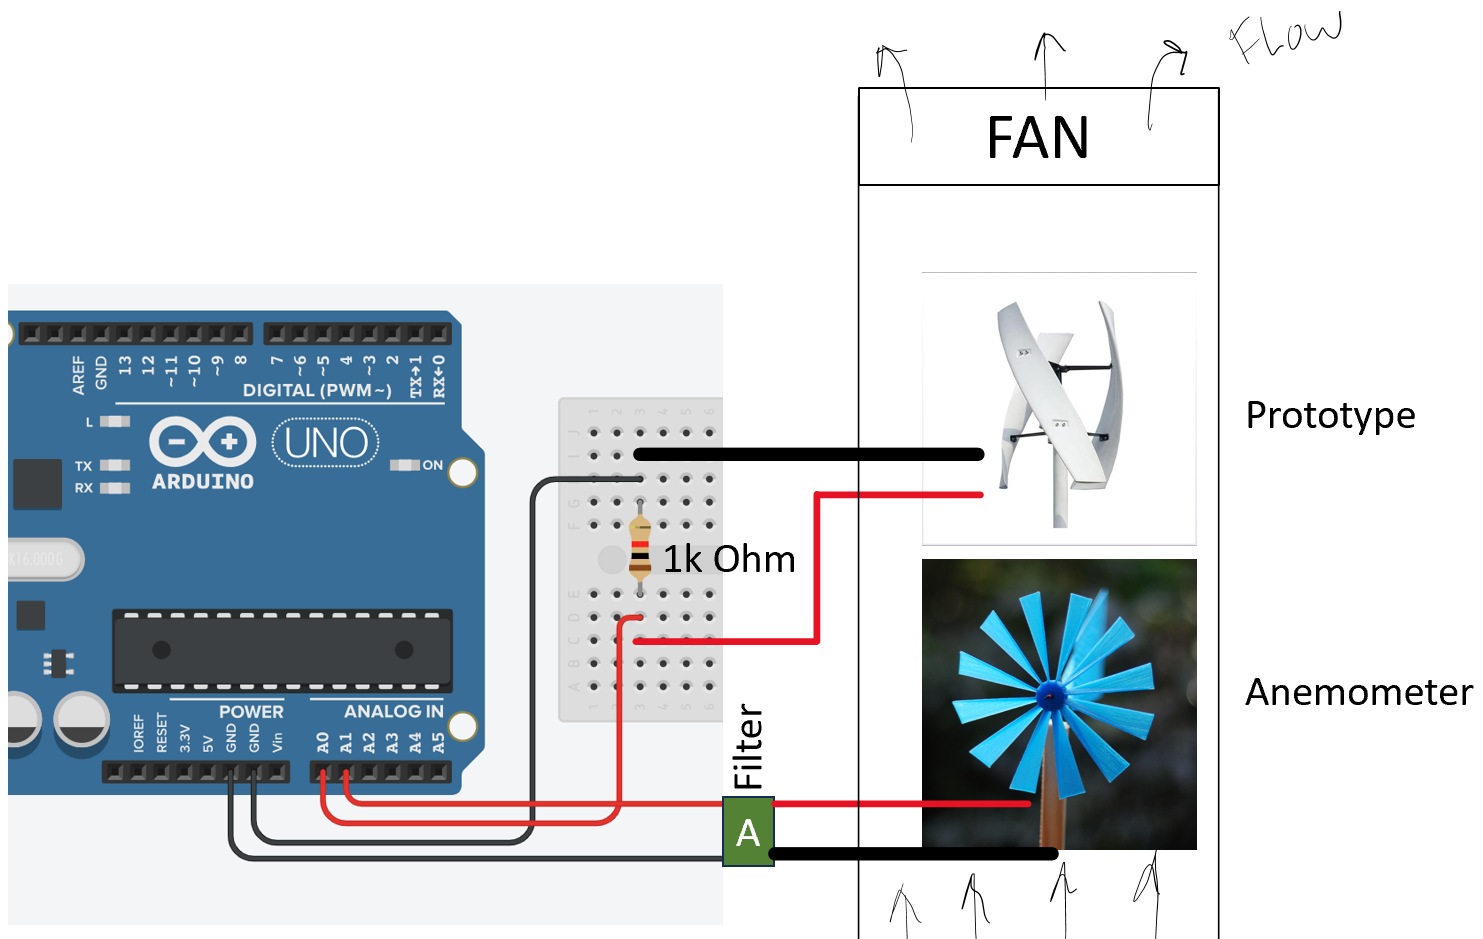

Figure: Circuit diagram of testing chamber

#### Example Collection Code

% ESPWindMeasurement.mlx
% Author: Fritz Geib (ftgeib@mtu.edu)
% Date: 11/21/2024
% Testing will Start from Fan Setting 6 down to Setting 1. 
% Testing Protocol will be to 
% - Run the fan for 1 minute at Setting 6 to get up to speed. 
% - Start the Collection Script
% - Wait 20 Seconds
% - Lower Fan Setting to next highest level (5,4,3,2,1)
% - Wait 20 Seconds
% - Repeat for each fan setting down to 1. 
% File results will be saved in the same directory as a .mat file with todays date
% and time. 

% Connect
clear 
a = arduino()                          % Connect to the first Arduino Seen

Updating server code on board Uno (/dev/cu.usbmodem11201). This may take a few minutes.


Failed to validate the server. Reprogram the board to proceed.


% Measure
Time = []; tic();                       % Start a timer for measuring
disp("Start")                           % Notify user of Start 
for i = 1:1500                           % loop our measurement code to collect
    Time(i) = toc();                   % Save the time elasped in seconds of the measurement
%    disp(Time(i));
    MeterVoltMeasurement(i) = a.readVoltage("A1"); % Save/Collect the Data
    PrototypeVoltMeasurement(i) = a.readVoltage("A0"); % Save/Collect the Data
    if PrototypeVoltMeasurement(i) > 0.2
        a.writeDigitalPin("D2", 1)
    else
        a.writeDigitalPin("D2", 0)
    end
    plot(Time(i), MeterVoltMeasurement(i), 'b*');
    hold on;
    plot(Time(i), PrototypeVoltMeasurement(i), 'r*'); 
    drawnow();
end
disp("end")                             % Notify user of end

% Save dataset vectors to a .mat file
save(Meter)
save([datestr(now,'yyyy.mm.dd.HH.MM.SS'),'.Recorded.mat'], "Time", "MeterVoltMeasurement", "PrototypeVoltMeasurement")

#### Analysis Example Code Block

Move this block below to a new file so that you can open your recorded data and perform the analysis and plotting stages. 

% Analysis

% load('myFilename.mat') % Load in a previously recorded data set

% Find Average Power for each of 6 wind speed settings

% Plot Prototype Power (watts) vs Wind Speed (m/s)
